## cse327hw7

ZianShang

###     Notes:

- The code performs better when points are chosen in order and near the center of the image

- Output is in grayscale

- The interp2() method of backward warping does not function well currently. It only gives the shape of the warped image, and I have not been able to fix it.

% Read images as src and dest
src = double(imread("img1.tif"));
dest = double(imread("img2.tif"));

% imshowpair(uint8(src), uint8(dest), "montage");

- Homography matrix estimation

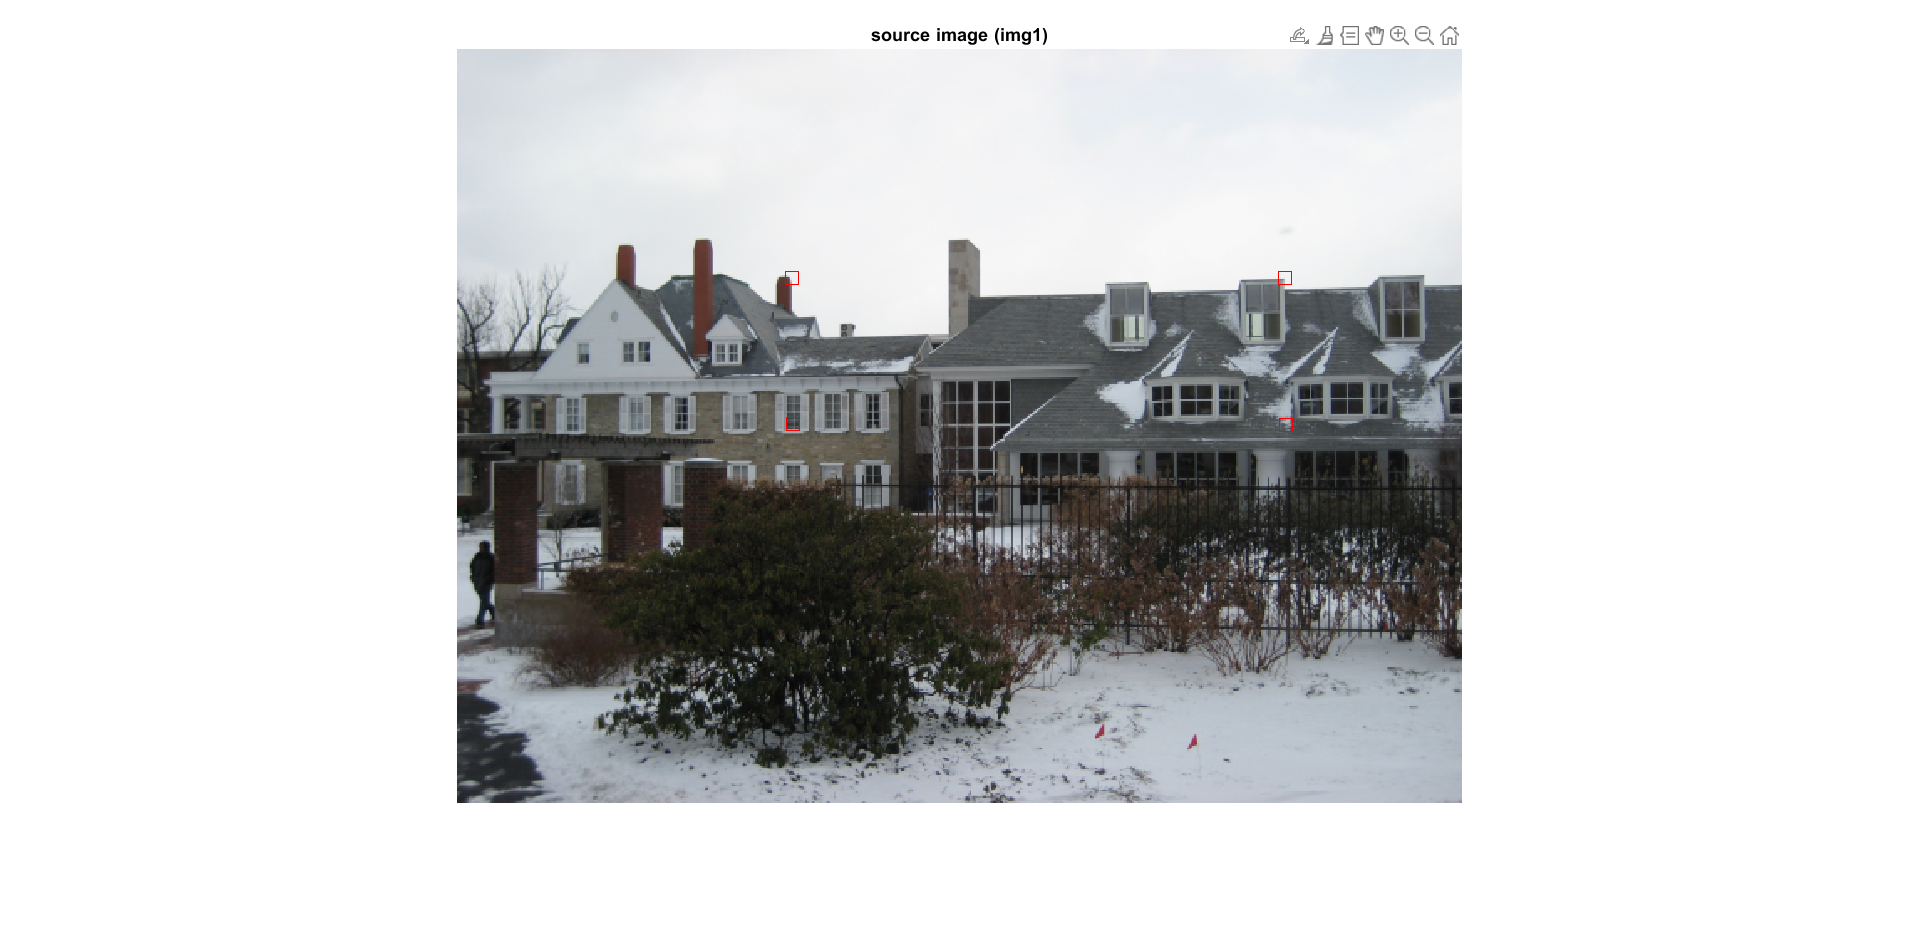

% Choose 4 points from src img
imshow(uint8(src));
title('source image (img1)');
[x,y] = ginput(4);

hold on; 
plot(x, y, 'rsquare', 'MarkerSize',10);
hold off;

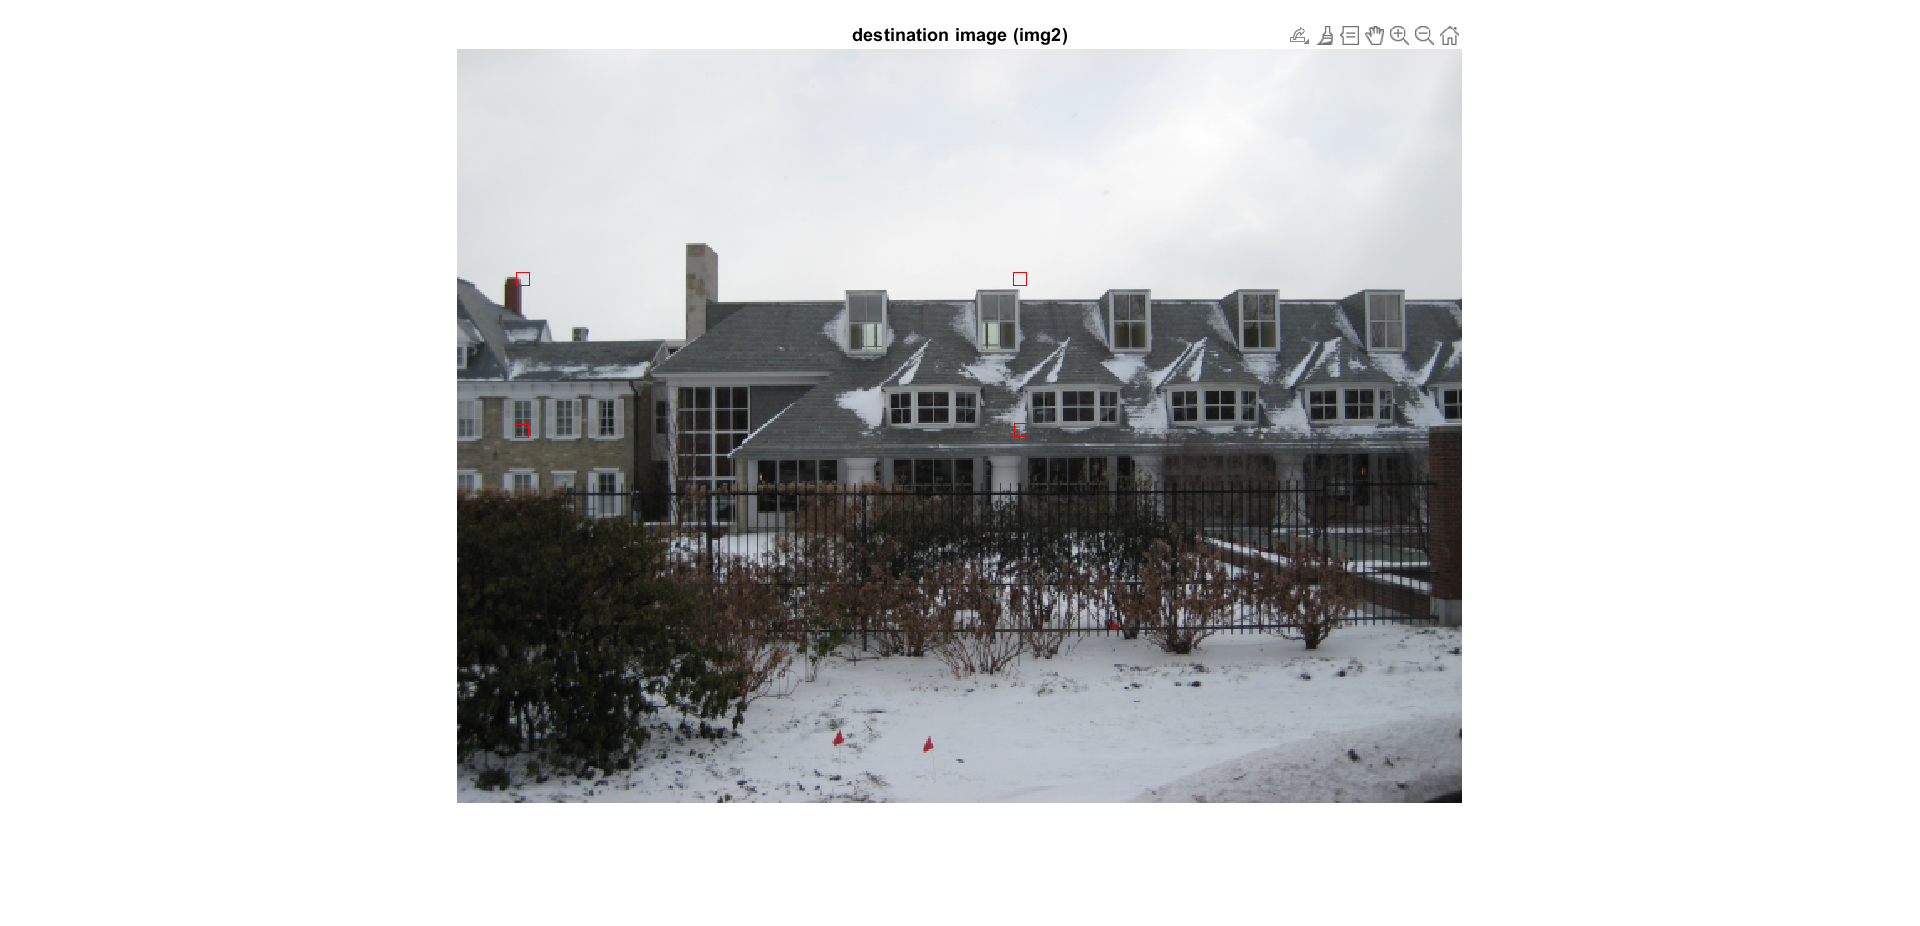


src_points = [x, y];

% Choose 4 points from dest img
imshow(uint8(dest));
title('destination image (img2)');
[x,y] = ginput(4);

hold on; 
plot(x, y, 'rsquare', 'MarkerSize',10);
hold off;

dest_points = [x, y];

% Display src & dest points here
disp(src_points);

  200.2347  136.8727
  494.4655  136.8727
  495.0623  224.6048
  200.8316  224.0080



disp(dest_points);

   39.6910  137.4695
  336.3090  137.4695
  336.9058  227.5889
   39.0942  228.1857



% Testing points
% src_points =[295.1286,  114.7905; 387.0385,  141.0504; 387.0385,  178.6499; 293.9350,  174.4721];
% dest_points =[ 137.5690,  118.9682; 231.8660,  145.2281; 233.0597,  182.2308; 138.1658,  177.4562];

% Compute the homography matrix by setting ||h|| = 1
A = zeros(2*size(dest_points, 1), 9);     % A is 2N*9

for i = 1:4
    x = src_points(i, 1);
    y = src_points(i, 2);
    x_pr = dest_points(i, 1);
    y_pr = dest_points(i, 2);

    A(2*i-1, :) = [x, y, 1, 0, 0, 0, -x*x_pr, -y*x_pr, -x_pr];
    A(2*i, :) = [0, 0, 0, x, y, 1, -x*y_pr, -y*y_pr, -y_pr];
end

% Extract the homography matrix H from the last column of V using vsd
[U, S, V] = svd(A);
H = reshape(V(:, end), 3,3)';
H = H / H(3, 3);
disp(H);

    1.0264   -0.0157 -163.5691
    0.0063    1.0334   -4.8516
    0.0000   -0.0000    1.0000



[V, D] = eig(A' * A);
[~, minEigenvalueIndex] = min(diag(D));
minEigenVector = V(:, minEigenvalueIndex);
H = reshape(minEigenVector, 3, 3)';
H = H / H(3, 3);
disp(H);

    1.0264   -0.0157 -163.5691
    0.0063    1.0334   -4.8516
    0.0000   -0.0000    1.0000



2. implement forward and backward warping using H

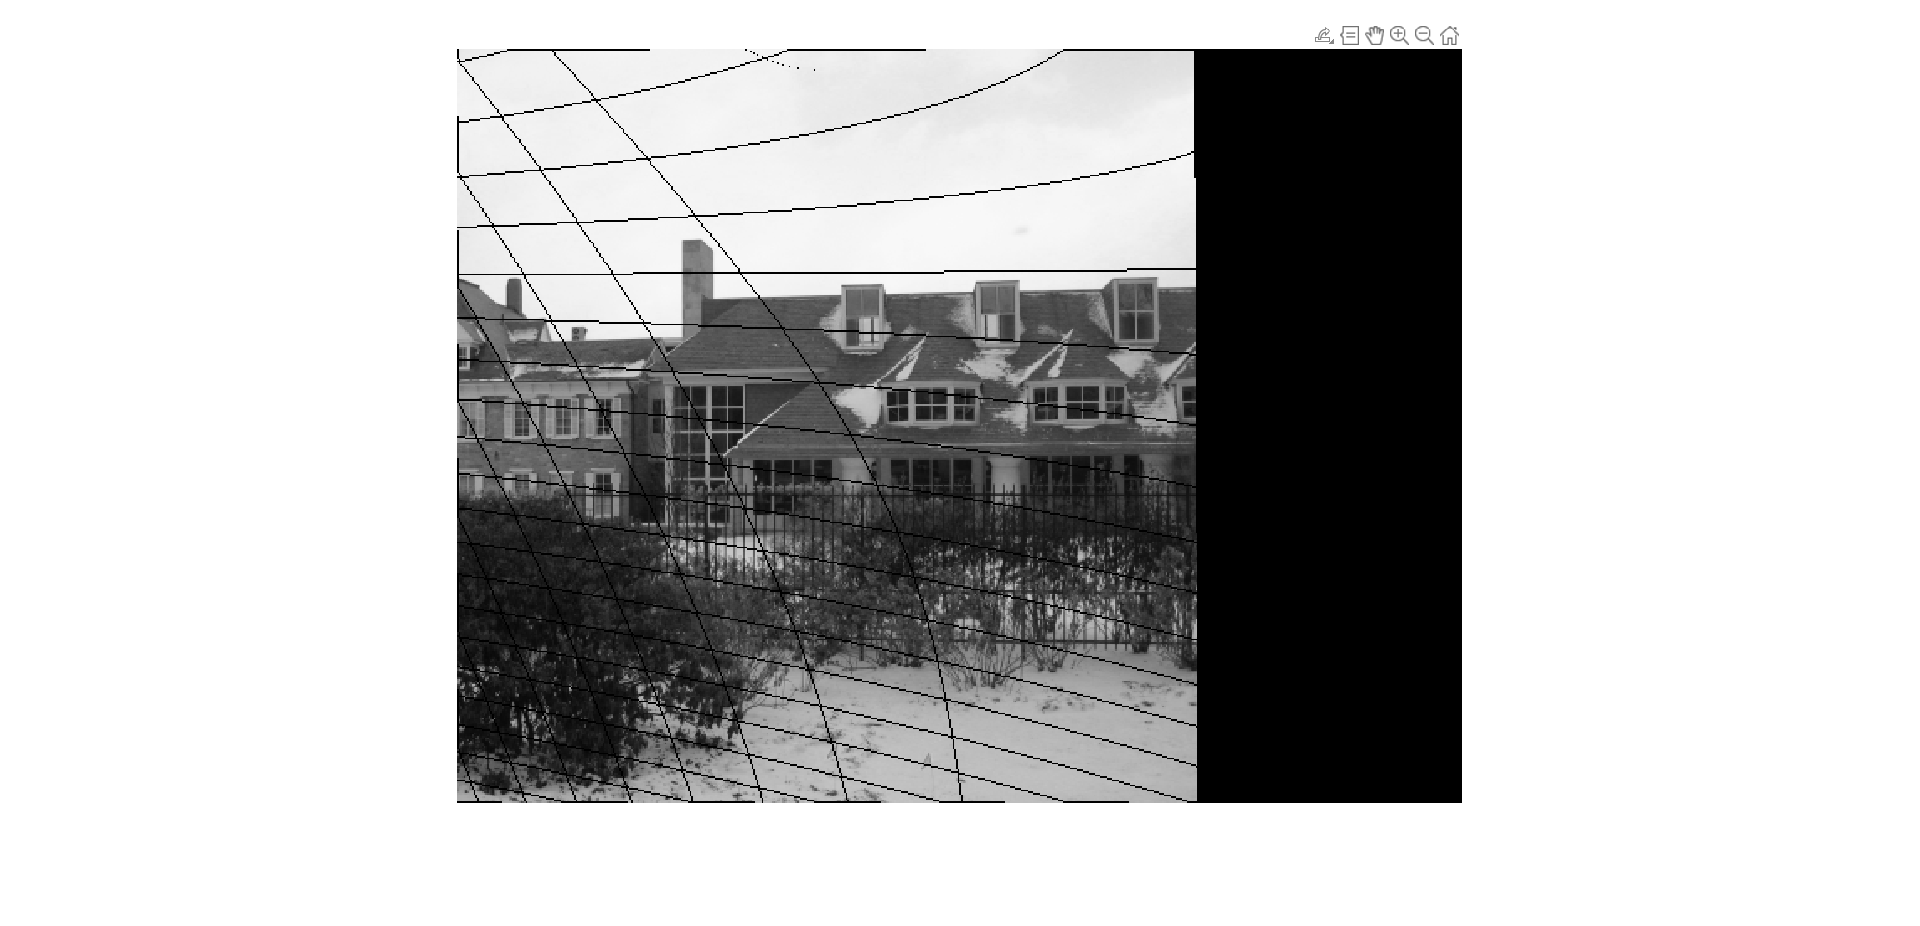

% Forward warping using the nearest neighbor

[n_rows_src, n_cols_src] = size(rgb2gray(src));
[n_rows_dest, n_cols_dest] = size(rgb2gray(dest));

% Initialize warped img
warpedImgForward = zeros(n_rows_src, n_cols_src);

for x = 1:n_cols_src
    for y= 1:n_rows_src

            p = [x;y;1];
            p_prime = H * p;
            x_prime = p_prime(1)/p_prime(3);
            y_prime = p_prime(2)/p_prime(3);

            % Check if the new position is out of boundary, if so, continue
            if x_prime<1 || x_prime>n_cols_dest || y_prime<1 || y_prime>n_rows_dest
                continue;
            end
            % Insert src density to warpted img
            warpedImgForward(round(y_prime), round(x_prime)) = src(y, x);
    end
end

imshow(uint8(warpedImgForward));

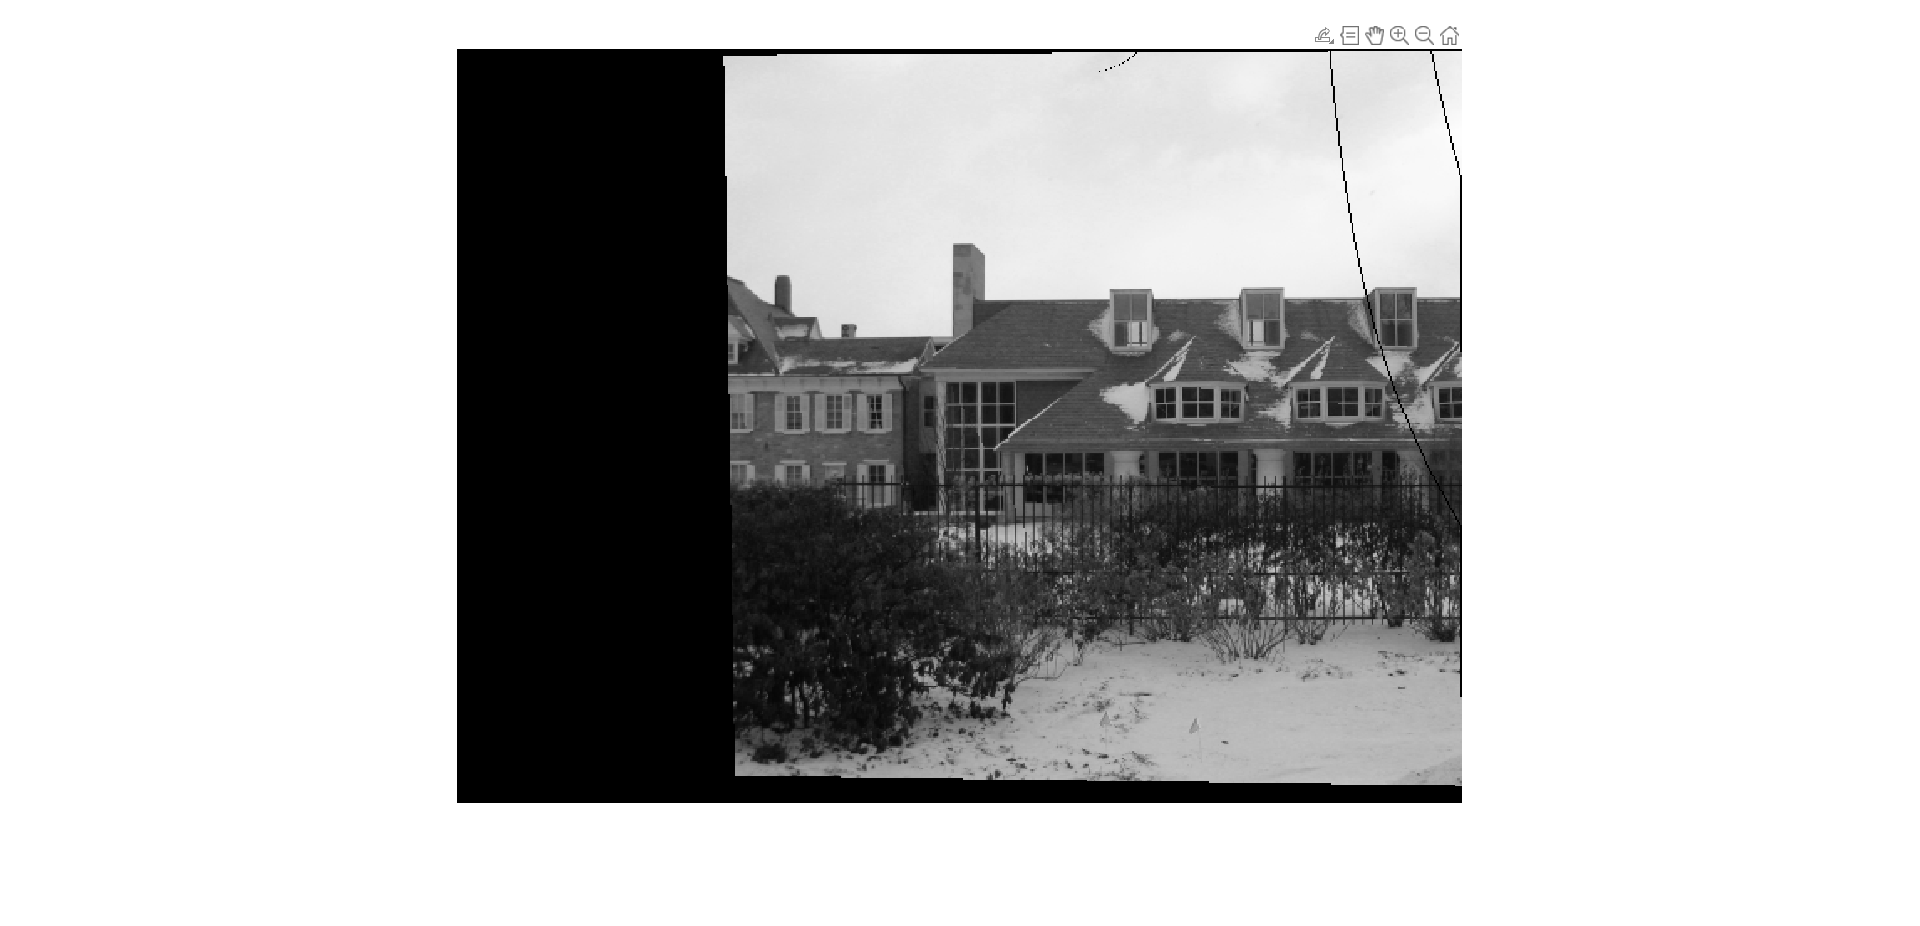

% Backward img warping using nearest neighbor or bilinear interpolation

% Initialize warped img
warpedImgBackward = zeros(n_rows_src, n_cols_src);

for x_prime1 = 1: n_cols_dest
    for y_prime1 = 1:n_rows_dest

        p_prime1 = [x_prime1; y_prime1; 1];
        p = H\p_prime1;

        x1 = p(1)/p(3);
        y1 = p(2)/p(3);

        % Check if the new position is out of boundary, if so, continue
        if x1<1 || x1>n_cols_src || y1<1 || y1>n_rows_src
            continue;
        end

        % Insert src density to warpted img

        % 1. nearest neighbor
        % warpedImgBackward(round(y1), round(x1)) = dest(y_prime1, x_prime1);

        % 2. bilinear
        a = x_prime1 - floor(x_prime1);
        b = y_prime1 - floor(y_prime1);
        
        I1 = (1-a)*(1-b)*dest(floor(y_prime1), floor(x_prime1));
        I2 = a*(1-b)*dest(floor(y_prime1), ceil(x_prime1));
        I3 = (1-a)*b*dest(ceil(y_prime1), floor(x_prime1));
        I4 = a*b*dest(ceil(y_prime1), ceil(x_prime1));

        I = I1 + I2 + I3 + I4;
        warpedImgBackward(round(y1), round(x1)) = I;
    end
end
imshow(uint8(warpedImgBackward));

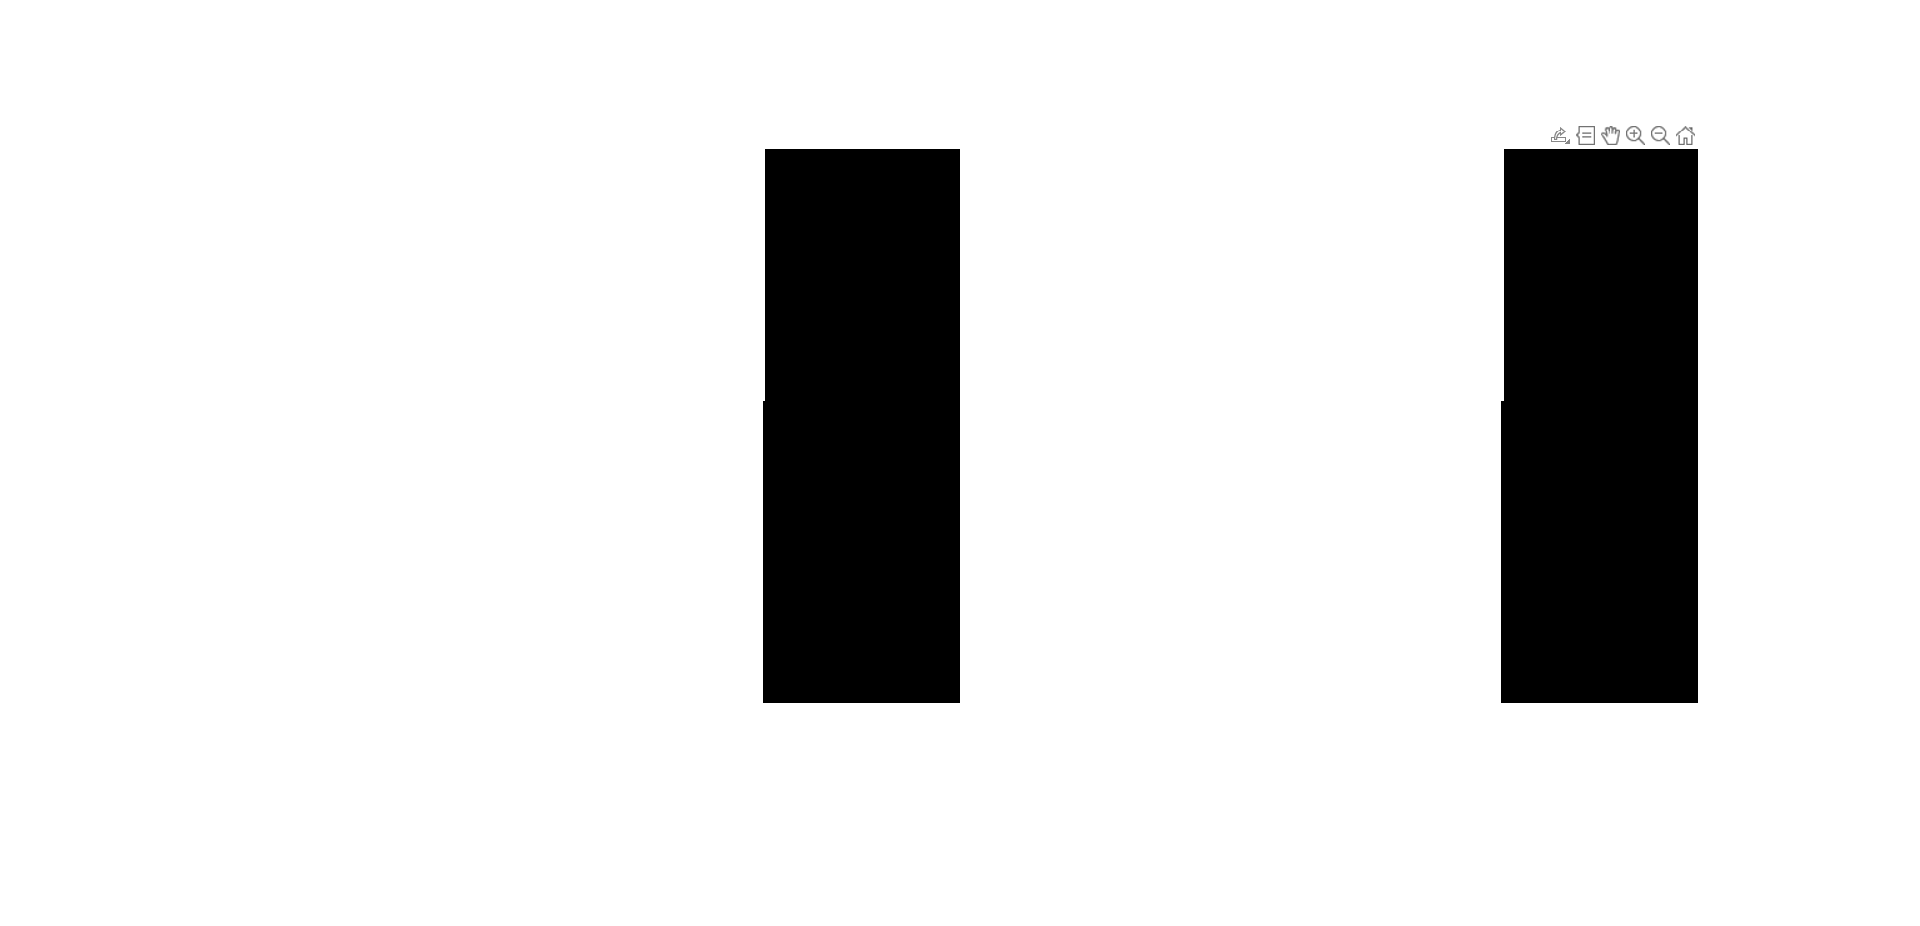

% Use interp2() for backward warping ??

[xi, yi] = meshgrid(1:n_cols_dest, 1:n_rows_dest);
src = rgb2gray(src);
dest = rgb2gray(dest);

H_inv = inv(H);
xx = (H_inv(1,1) * xi + H_inv(1,2) * yi + H_inv(1,3)) ./ (H_inv(3,1) * xi + H_inv(3,2) * yi + H_inv(3,3));
yy = (H_inv(2,1) * xi + H_inv(2,2) * yi + H_inv(2,3)) ./ (H_inv(3,1) * xi + H_inv(3,2) * yi + H_inv(3,3));

warped_image = interp2(src, xx, yy);
imshowpair(warped_image, uint8(warped_image), "montage");